# DAEDALUS model and experimental data comparison

clc
clear 
close all

Load data

daedalus_exp_height = readmatrix("studies\DAEDALUS\height_deadalus_exp.csv")

daedalus_exp_height = 1.0e+04 *

   -0.0001    7.4724
    0.0015    7.3804
    0.0029    7.0307
    0.0037    6.7546
    0.0045    6.4785
    0.0050    6.1288
    0.0057    5.7975
    0.0062    5.5767
    0.0067    5.2270
    0.0071    4.9877


daedalus_sim_height = readmatrix("studies\DAEDALUS\height_deadalus_model.csv")

daedalus_sim_height = 1.0e+04 *

    0.0004    7.5112
    0.0014    7.4173
    0.0021    7.2921
    0.0027    7.1356
    0.0035    6.9061
    0.0041    6.6975
    0.0045    6.5306
    0.0049    6.3845
    0.0052    6.1967
    0.0055    6.0194


daedalus_sim_ang_vel = readmatrix("studies\DAEDALUS\vel_angl_deadalus_model.csv")

daedalus_sim_ang_vel = 1.0e+03 *

    0.0145    0.0045
    0.0261    0.0295
    0.0354    0.0817
    0.0410    0.1406
    0.0448    0.2019
    0.0466    0.2382
    0.0494    0.2972
    0.0522    0.3652
    0.0550    0.4628
    0.0587    0.5603


daedalus_sim_vel = readmatrix("studies\DAEDALUS\vel_deadalus_model.csv")

daedalus_sim_vel =    -0.3841   22.1713
    3.0730   40.5199
    5.3777   70.3364
    7.6825   92.5076
    9.9872  109.3272
   12.2919  123.0887
   13.8284  136.8502
   16.1332  161.3150
   17.6697  178.8991
   19.2062  192.6606


daedalus_exp_vel = readmatrix("studies\DAEDALUS\vel_deadalus_exp.csv")

daedalus_exp_vel =    96.4765  487.5000
  100.6711  406.9444
  100.6711  441.6667
  104.0268  368.0556
  109.0604  322.2222
  114.0940  252.7778
  120.8054  215.2778
  127.5168  186.1111
  137.5839  161.1111
  149.3289  133.3333


% simulation data
data_sim = load("studies\DAEDALUS\daedalus.mat").out

data_sim = struct with fields:
                  main_clock: [20879×1 double]
            vehicle_position: [20879×3 double]
            vehicle_velocity: [20879×3 double]
        vehicle_acceleration: [20879×3 double]
         vehicle_orientation: [20879×3 double]
    vehicle_ang_acceleration: [20879×3 double]
        vehicle_ang_velocity: [20879×3 double]
                     F_rotor: [20879×3 double]
                   F_gravity: [20879×3 double]
             F_drag_cilinder: [20879×3 double]
                     F_total: [20879×3 double]
                     T_rotor: [20879×1 double]
                     T_total: [20879×3 double]
                 temperature: [20879×1 double]
                    pressure: [20879×1 double]
                     density: [20879×1 double]
           dynamic_viscosity: [20879×1 double]
         kinematic_viscosity: [20879×1 double]
                 sound_speed: [20879×1 double]
              rotor_velocity: [20879×1 double]
          rotor_acceleration:

#### Vehicle Position

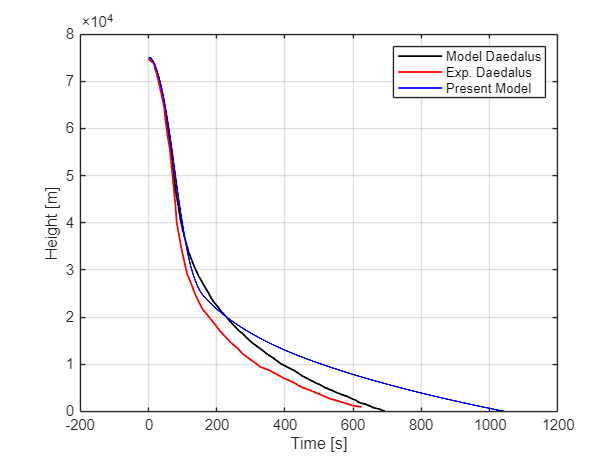

figure()
plot(daedalus_sim_height(:,1), daedalus_sim_height(:,2), 'k', 'LineWidth',1.2)
hold on
plot(daedalus_exp_height(:,1), daedalus_exp_height(:,2), 'r', 'LineWidth',1.2)
plot(data_sim.main_clock, data_sim.vehicle_position(:,3), 'b', 'LineWidth',1.2);
grid on;
xlabel("Time [s]")
ylabel("Height [m]")
legend("Model Daedalus", "Exp. Daedalus", "Present Model")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'height_daedalus', '-depsc')  % EPS a cores

#### Vehicle Velocity

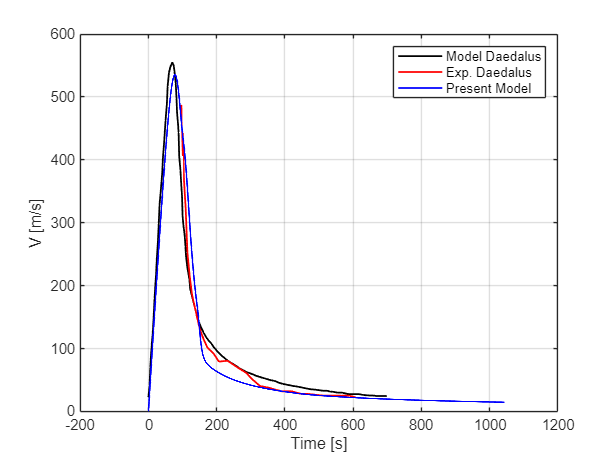

figure()
plot(daedalus_sim_vel(:,1), daedalus_sim_vel(:,2), 'k', 'LineWidth',1.2)
hold on
plot(daedalus_exp_vel(:,1), daedalus_exp_vel(:,2), 'r', 'LineWidth',1.2)
plot(data_sim.main_clock, -data_sim.vehicle_velocity(:, 3), 'b', 'LineWidth',1.2);
grid on;
xlabel("Time [s]")
ylabel("V [m/s]")
legend("Model Daedalus", "Exp. Daedalus", "Present Model")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'velocity_daedalus', '-depsc')  % EPS a cores

#### Rotor Velocity

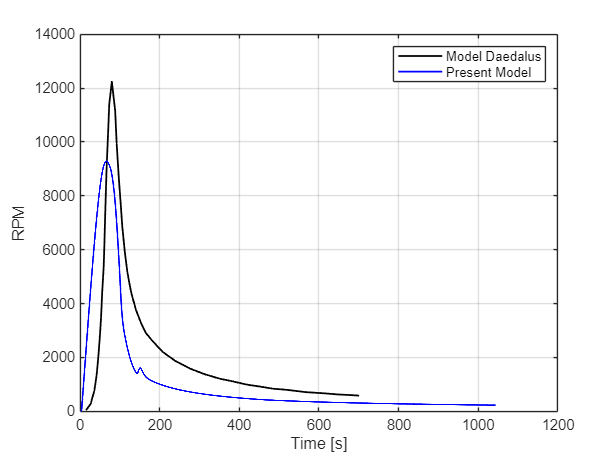

figure()
plot(daedalus_sim_ang_vel(:,1), daedalus_sim_ang_vel(:,2) * 60 /(2*pi), 'k', 'LineWidth',1.2)
hold on
plot(data_sim.main_clock, data_sim.rotor_rpm, 'b', 'LineWidth',1.2);
grid on;
xlabel("Time [s]")
ylabel("RPM")
legend("Model Daedalus", "Present Model")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rpm_daedalus', '-depsc')  % EPS a cores

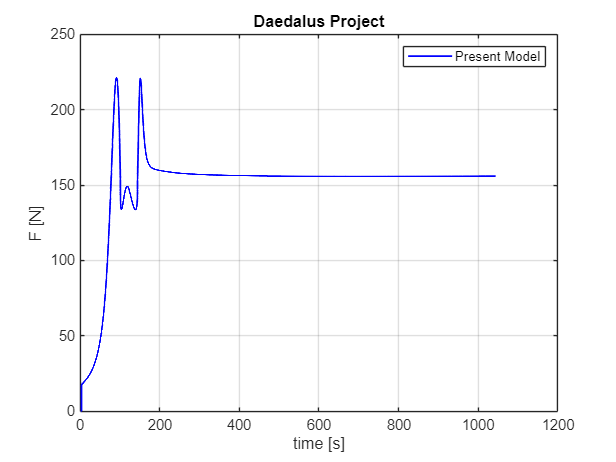


figure()
plot(data_sim.main_clock, data_sim.F_rotor(:,3), 'b', 'LineWidth',1.2);
grid on;
xlabel("time [s]")
ylabel("F [N]")
title("Daedalus Project")
legend("Present Model")
saveas(gcf, 'force_daedalus.eps')

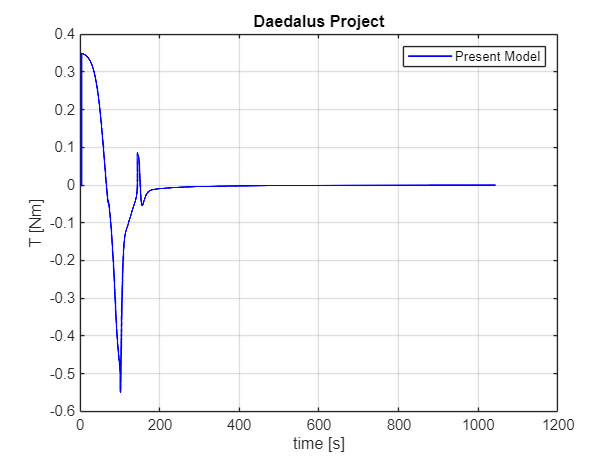

figure()
plot(data_sim.main_clock, data_sim.T_rotor, 'b', 'LineWidth',1.2);
grid on;
xlabel("time [s]")
ylabel("T [Nm]")
title("Daedalus Project")
legend("Present Model")
saveas(gcf, 'torque_daedalus.eps')